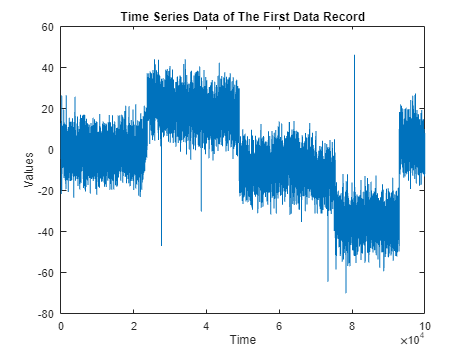

DataStruct = load('data.mat');
Data = DataStruct.data;
Event = DataStruct.event;
X1 = Data(1).x;
Time1 = Data(1).time;

plot(Time1,X1);
title('Time Series Data of The First Data Record');
xlabel('Time');
ylabel('Values');


CorruptIdx_event = find(isnan(Event)|isinf(Event));
for i = 1:100
    % find corrupted data NaN or Inf values
    CorruptIdx_X = find(isnan(Data(i).x)|isinf(Data(i).x));
    CorruptIdx_time = find(isnan(Data(i).time)|isinf(Data(i).time));
    if isempty(CorruptIdx_X)==0
        disp('index of data records with nan values');
        disp(i);
    end
    if isempty(CorruptIdx_time)==0
        disp('index of time with nan values');
        disp(i);
    end
end

index of time with nan values


    57




% we can observe 57th time records are bad
% so remove since the whole data record is bad
Data(57)= [];

The process is to divide the whole dataset into windows. Then, compare empirical cdfs from the latest to one previous window using Kolmogorov-Smirnov test. If null is not rejected, than there is no statistical evidence exists that two empirical CDFs are different from each other and we can merge two windows and compare with more previous windows. If null hypothesis is not rejected with the earlies window, than we can conclude that the time series data is stationary.  the As we can observe from the result, h = 1 and this means  Kolmogorov-Smirnov test  rejects null  hypothesis at the 5% significance level. By the definition, A process is ergodic if its statistical properties can be found by observing one sample function of the process over time. Since null  hypothesis is rejected, the results sugeested that there is no evidence exists to show that statistical properties can be found.

win_num = [5 10 50 100 1000]

win_num =            5          10          50         100        1000


test_results1 = zeros(99,5);
for d=1:99
    X = Data(d).x;
    % divide the dataset into non-overlapping windows, where each window has
    % more than 5 data
    for i=1:length(win_num)
        windows = create_windows(win_num(i), X);
        % conduct ks test from right to left, if null hypothesis is rejected than
        % break out of for loop
        % from right to left
        for j=1:length(windows)
            if j == 1
                prevWin = windows{length(windows)-j+1};
                continue
            end
            curtWin = windows{length(windows)-j+1};
            h = kstest2(prevWin,curtWin);
            % if not 
            if h==1
                test_results1(d,i) = h; 
                break
            end
            prevWin = [curtWin prevWin];
        end
    end
end

test_results2 = zeros(99,5);
for d=1:99
    X = Data(d).x;
    % we can also test from left to right
    for i=1:length(win_num)
        windows = create_windows(win_num(i), X);
        % conduct ks test from right to left, if null hypothesis is rejected than
        % break out of for loop
        % from left to right
        for j=1:length(windows)
            if j == 1
                prevWin = windows{j};
                continue
            end
            curtWin = windows{j};
            h = kstest2(prevWin,curtWin);
            % if not 
            if h==1
                test_results2(d,i) = h; 
                break
            end
            prevWin = [curtWin prevWin];
        end
    end
end

% results
disp(find(~test_results1));
disp(find(~test_results2));

From  differences between adjacent elements and the histogram plot, we can observe that this is stochastic sampling interval as the difference in time intevals are not the same and theplot is not a delta function.  By definitions, constant sampling intervals mean data is recorded or collected at a constant time interval. Stochastic sampling intervals mean data is collected at nonuniform time intervals. For data analysis, it is relativly easier to identify patterns or trends in data. In comparision, it is more challenging to identity patterns or trends due to randomness On the other hand, the real world system is more like stochastic sampling, becuase events happend at random. 

One way to correct for stochastic sampling is interpolation. It can be used to construct new data points within the range of a discrete dataset to estimate non-stochastic sampling.  There duplicate points which cause errors in matlab interpolation functions. One way to correct is to take mean of those values and another way is to remove points that are way off the distribution. Not correcting stochastic samplings is problematic, as the system become more unpredictable. It is not problematic to all cases depending on the nature of the systems and the purpose of data analysis. If stochastic sampplings are not completly unpredictable, than correcting might no be the best option.

interval = diff(Time1);
disp(interval(1:5));

   11.5623    9.5009   10.4951    8.5353   13.4539



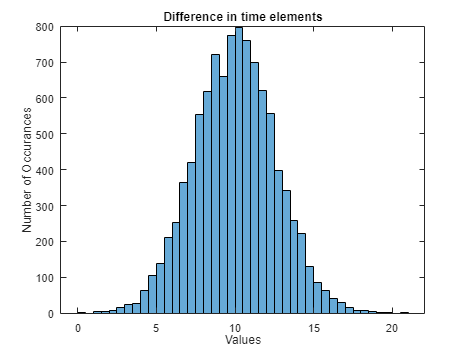

histogram(interval);
title('Difference in time elements');
xlabel('Values');
ylabel('Number of Occurances');

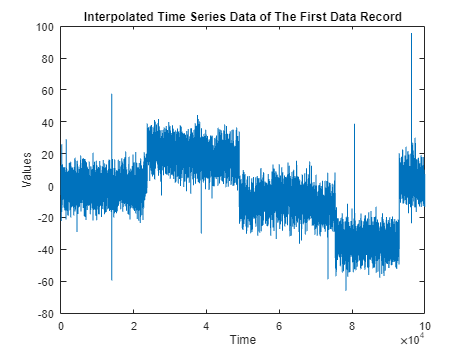


InterpoData = zeros(99,10000);
InterpoTime = zeros(99,10000);
% find duplicate times
for i=1:99
    Time = Data(i).time;
    X = Data(i).x;
    [uniqueTime, ia, ic] = unique(Time,'first');
    indexToDupes = find(not(ismember(1:numel(Time),ia)));
    m = mean([X(indexToDupes-1) X(indexToDupes)]);
    X(indexToDupes-1) = m;
    X(indexToDupes) = [];
    Time(indexToDupes) = [];
    query = 0:10:99990;
    interpolations = spline(Time,X,query);
    InterpoData(i,:) = interpolations;
    InterpoTime(i,:) = query;
end

plot(InterpoTime(1,:),InterpoData(1,:));
title('Interpolated Time Series Data of The First Data Record');
xlabel('Time');
ylabel('Values');

Coarse quantization refers to the process of rounding data points to nearest upper or lower bounds of values. So the dataset is not coarsely quantized, because coarsely quantized data have many duplicate values due to data assigned to nearest upper or lower bounds and present uniform distributions.

One impact of coarsely quantized data is information loss, since the roundings will lose details and differences in values could be eliminated.  Another impact mentioned in Status Data Characteristic is that Coarse quantization results in signal-dependent noise that cannot be simply modeled or isolated. Moreover, noise has large impacts on the quantization process.

To correct coarsely quantized data, we can apply wavelet denoise process with wavelet functions and threshold methodologies. It is correctable, but challenging. As stated in related literatures, coarsely quantized signals exhibit signal-dependent noise. This noise cannot be modeled as Gaussian. So it cannot be easily modeled or isolated as stated above.

disp('Number of unique values');

Number of unique values


disp(length(unique(InterpoData(1,:))));

       10000



The assumption that median filter makes is that noise is not gaussian, since it approximates deviations by using median absolute deviations and replaces target data that are two large by the median of a window of data samples centered around target data.

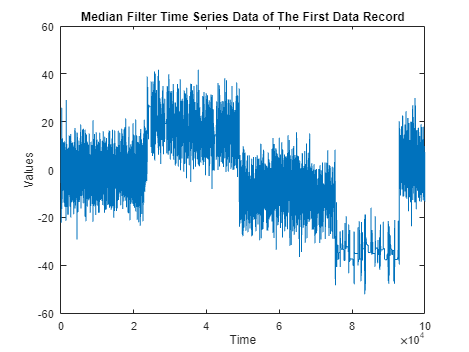

% apply median filter
med_data = median_filters(InterpoData,10);
plot(InterpoTime(1,:),med_data (1,:));
title('Median Filter Time Series Data of The First Data Record');
xlabel('Time');
ylabel('Values');

Through Wavelet Signal Denoiser App, I found best parameters for wdenoise function.

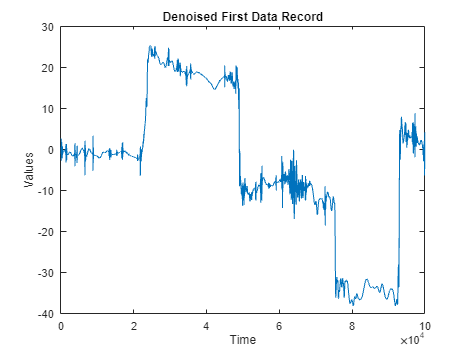

% Wavelet signal denoising
sample_data = med_data(1,:);
xden = wdenoise(sample_data,10, ...
    Wavelet='db10', ...
    DenoisingMethod='BlockJS', ...
    ThresholdRule='James-Stein', ...
    NoiseEstimate='LevelIndependent');

plot(InterpoTime(1,:),xden);
title('Denoised First Data Record');
xlabel('Time');
ylabel('Values');

Wavelet denoising provides a improved denosing approach over classical noise filtering methods.Classical frequency based filtering techniques are unsuitable because they assume data is stationaty and cannot handle non-stationary data for accurate estmate within regions of behavioural change. In comparison, wavlet denoising is able to use a variety of resoluttions or scales and handle non-stationary behaviours. So wavlet denoising provides a improved denoise approach. If we applied low pass filtering approach, the signal would look like stationary with fixed frequency.

Denoised_Data = zeros(99,10000);
for i = 1:99
    Denoised_Data(i,:) = wdenoise(med_data(i,:),10, ...
    Wavelet='db10', ...
    DenoisingMethod='BlockJS', ...
    ThresholdRule='James-Stein', ...
    NoiseEstimate='LevelIndependent');
end

The corrections are appropriate when discontinuities do not contain meaningful information. The corrections are inappropriate when they distort or remove useful information. The methodology for correcting discontinuity: 1. decompose signal with coefficients. 2. set up hard threshold. 3. reconstruct signal. This methodology will not work for real-time. One issue with real world data is to set up threshold, the hard threshold have to be adjusted accordingly with behavior of real-time data and different detail coefficient.  

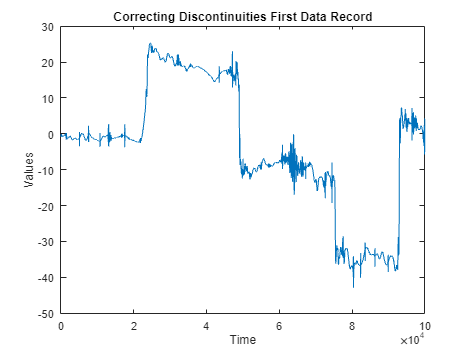

result = zeros(99,10000);
for i = 1:99
    result(i,:) = discontinuity_removal(2, Denoised_Data(i,:), 3);
end

plot(InterpoTime(1,:),result(1,:));
title('Correcting Discontinuities First Data Record');
xlabel('Time');
ylabel('Values');

Matched filter compares a known event with unknown signal to recognize existence of known event within the unkown signal. Matched filter assumes that there is a reference signal (event), noise is white gaussian and constant sampling intervals.  Matched filter works when noise is gaussian and does not work when noise is non-guassian, becuase it generates an output to maximize the output peak power ratio to mean noise power within its frequency response. Matched filter works with constant sampling intervals and does not work with stochastic sampling intervals, becuase stochastic sampling intervals can cause trouble when comparing event with the signal.

% matched filter
mf_data = zeros(99,1);
for i = 1:99
    mf_data(i) = matched_filters(result(i,:),Event);
end

Functions 

function wins = create_windows(num_windows, D)
    % use floor in case of vector size is undivisible
    P = floor(length(D)/num_windows);
    L = length(D) - num_windows*P;
    cols = [P*ones(1, num_windows-L) (P+1)*ones(1, L)]; 
    wins = mat2cell(D, 1, cols);
end

% apply median filter
function result = median_filters(records,Winsize)
    result = zeros(99,10000);
    halfWinsize = floor(Winsize/2);
    for i=1:99
        r = records(i,:);
        % create sliding window
        for j=1:length(r)
            if (j - halfWinsize)<=0
                window = r(1:Winsize);
            elseif (j + halfWinsize)>length(r)
                window = r((length(r) - Winsize):length(r));
            else
                window = r(j - halfWinsize : j + halfWinsize);
            end
            % find median absolute values
            M = mad(window,1);
            % if data is too large then replace with median values
            if abs(r(j))>8*M
                med = median(window);
                r(j) = med;
            end
        end
        result(i,:) = r; 
    end
end

function result_signal = discontinuity_removal(level, x, threshold)
    % wavelet decomposition
    [C,L] = wavedec(x,level,'db6');
    % extracts the approximate detail coefficients
    a5=appcoef(C,L,'db6',level);
    [d1, d2] = detcoef(C,L,1:level);
    % hard thresholding
    d1_thard = wthresh(d1, 'h', threshold);
    d2_thard = wthresh(d2, 'h', threshold);
    C_filtered = [a5 d1_thard d2_thard];
    %nc = wthcoef("d",C,L,1:5);
    result_signal = waverec(C_filtered, L, 'db6');
end

% function matched filter
% compare windows of a signal with event
function result = matched_filters(records,events)
    v = zeros(length(records)-length(events),1);
    for i = 1:(length(records)-length(events))
        win = records(i:(i+length(events)-1));
        v(i) = win*events';
    end
    [M,result] = max(v);
end